# Paper3: 1st test - network architecture

How will a 4*8 binocular patch work?

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Library/CloudStorage/OneDrive-Personal/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveToFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper3PlotingData/']; % V1D2
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_Binocular/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/LARGE16/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/25Function_binocular_realLGN/']; % V1D2
DataFolder4 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

addpath(DataFolder4)
addpath(SaveToFolder)
addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPt = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPt))

CurrentFolder = pwd;
FigurePaperPath = [CurrentFolder '/Figures/Demo042524/']; % V1D2
close all

## 2. Set up LDE firing rate functions

first get basic function information

%AngleList = {'0.0'}; % only vertical for now
AngleList = {'0.0','7.5','15.0','22.5'};
DomList =  {'Small','Large','LARGER'};

## 3. Set up initial conditions

N_HCOutX = 4; N_HCOutY = 8; PixNumOut = N_HCOutX*N_HCOutY*NPixX*NPixY;
N_HCinX = 4; N_HCinY = 4;
NPixX = 10; NPixY = 10;

Parameters of L4 kernels

KerTest = 4;

MonocuFlag = false;
%ParaIx = 0;   ParaIy = 1;
%TestEx = 0:0.2:1; TestEy = 0:0.2:1;
TestEx = 1; TestEy = 1;
aa = length(TestEx); bb = length(TestEy);
TestNum = KerTest*2;
ICTestAll = cell(TestNum,1);
AngleTestAll = [zeros(KerTest,1);22.5*ones(KerTest,1)]; % 0:7.5:22.5; % has to be multiples of 7.5
L6pars = cell(TestNum,1);
L6pars{4} = {2.5,3,62.5,117.5,95.5};
L6pars{3} = {3,3,40, 53,50, 70,60, 130,90}; 
L6pars{2} = {3,3,60, 120,90}; 
L6pars{1} = {3,3};
for L6parId = 1:KerTest
    L6pars{KerTest + L6parId} = L6pars{L6parId} ;
end
% The first 2: y = a(x-b); the next three: if y> 60, y_1 = 60 + (y-60)*(90-60)/(120-60); 

TestExMat = repmat(TestEx,TestNum,1); TestEyMat = repmat(TestEy',1,TestNum);
TestExSeq = TestExMat(:); TestEySeq = TestEyMat(:); 

Background

% LDEbgIC.S = 2.5*ones(N_HCOutX*NPixX*N_HCOutY*NPixY,1);
% LDEbgIC.C = 8*ones(N_HCOutX*NPixX*N_HCOutY*NPixY,1);
% LDEbgIC.I = 18*ones(N_HCOutX*NPixX*N_HCOutY*NPixY,1); %16
% LDEICOut = LDEbgIC;

%%%60 deg: by rotating 15 deg pattern

Start from 90, then go to 22.5

ICData = load(sprintf('LDETracesV4D2_NewSmear_ang0.0.mat'));
load('LDETracesV4D2_NewSmear_ang0.0.mat')
LDEICPart = ICData.LDEEquv;

LDEICOut = HCRotXY(LDEICPart,0,N_HCinX,N_HCinY,N_HCOutX,N_HCOutY,NPixX,NPixY,0);
for TestId = 1:TestNum
    ICTestAll{TestId} = LDEICOut;
end
LDEOutAll = cell(size(ICTestAll));
LDEIL2Diff = cell(size(ICTestAll));
L2DiffNormNeib = cell(size(ICTestAll));
NANFlag = false(size(ICTestAll));
%BGFlagAllTest = cell(size(ICTestAll));

Hyperparameters of iterations

p = 0.33;% 1-p for the original input
EpocTest = 300;
ExportFlag = 'xn';

L2Diff_OneStepAll = zeros(length(ICTestAll),EpocTest+1);
DiffVecAll = zeros(length(ICTestAll),EpocTest+1,3*NPixY*NPixX);

Since we are doing different network architectures now - need to separate inputs to the S C I functions!!!

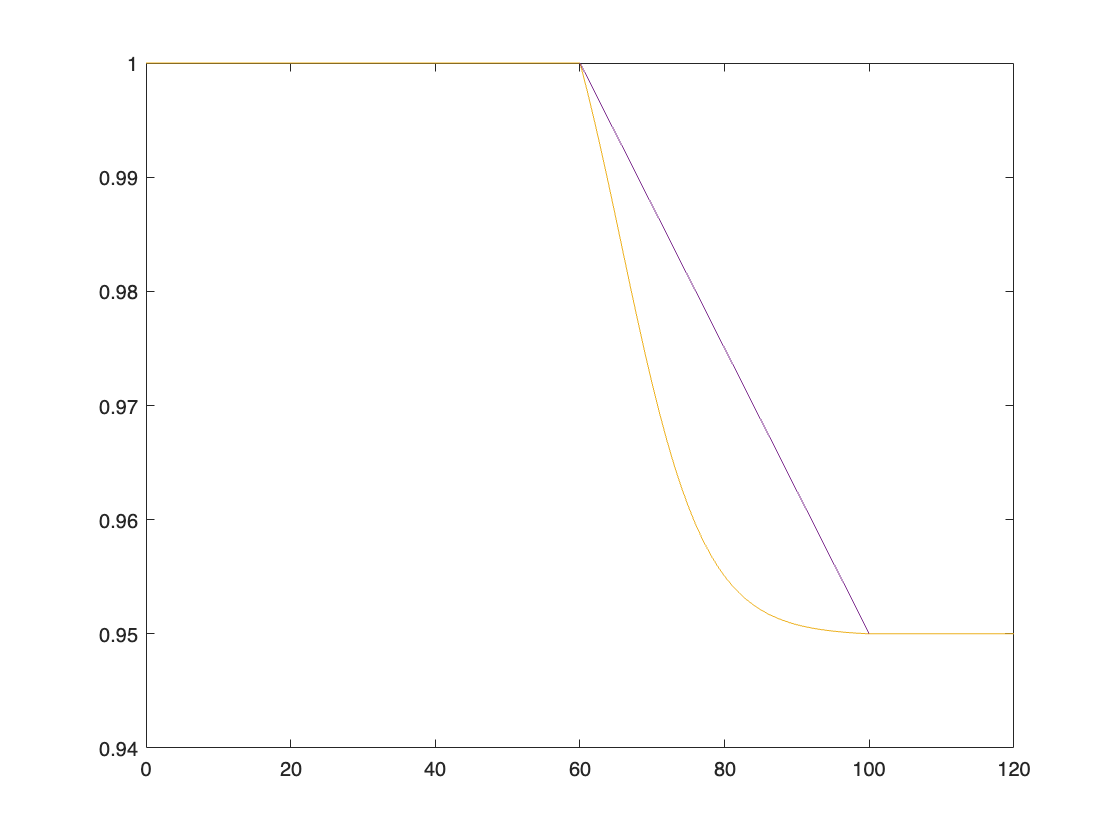

% Determine L4 Input from a range
L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
for PInd = 1:N_HC*NPixX*N_HC*NPixY
L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec);
L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec ;
L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec);
L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec ;
L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec);
L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec ;
end
L4Eall = L4SE+L4CE+L4IE; L4Iall = L4SI+L4CI+L4II;
L4SEp = mean(L4SE./L4Eall);L4CEp = mean(L4CE./L4Eall);L4IEp = mean(L4IE./L4Eall);
L4SIp = mean(L4SI./L4Iall);L4CIp = mean(L4CI./L4Iall);L4IIp = mean(L4II./L4Iall);

% LGN and L6 info
lgnSF = 2.5; lgnTF = 10;
ExpTex = 'CtrlL4';
Comment = ['L6Real' ExpTex];
% Inhibition saturation info
IKp.Thrsld = 60; IKp.Highist = 100;  IKp.Slope = 0.95; % this is for new rule: multiplicative saturation
Isaturation = true;
IKp.Mode = 'sigmoid'; % or 'linear'
IKp.IntH = 6;
IKp.IntL = 1; % one side start from 3. another side start from 6

figure(100)
[yy,fac] = InhMulp(0:120,IKp);
plot(0:120,fac)
hold on
plot(60:100,1-(0:40)*0.05/40)

## 6*6 tests

We start from 1. BG for both eyes, and 2. Vertical for both eyes. Target: BG for left and vertical for right

for TestId = 1:TestNum
    AngleInpt = AngleTestAll(TestId)
    L6pars{TestId}
    Isaturation

    RotInd = floor(AngleInpt/45); % 0-3
    MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
    switch MirInd % find the corresponding source
        case 0
            AngSource = mod(AngleInpt,45);
        case 1
            AngSource = mod(-AngleInpt,45);
    end
    
    % Use the source, decide which response function for angle should I use
    AngFuncCtgrCdid = 0:7.5:22.5;
    [~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));
    
    AngPrint = AngleList{AngFuncCtgr};
    Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5

load all precomputed domains

    L4EmeshXAll = cell(size(DomList));
    L4ImeshYAll = cell(size(DomList));
    LDEFrfuncAll = cell(size(DomList));
    for DomInd = 1:length(DomList)
        FuncTemp = load(sprintf('Func135%s-%s-Ang%s-SF%.1fTF%d-%s.mat',...
            DataPt,Comment,AngPrint,lgnSF,lgnTF,DomList{DomInd}),...
            'LDEFrfunc','L4EmeshX','L4ImeshY');
        L4EmeshXAll{DomInd} = FuncTemp.L4EmeshX;
        L4ImeshYAll{DomInd} = FuncTemp.L4ImeshY;
        LDEFrfuncAll{DomInd} = FuncTemp.LDEFrfunc;
    end

## 4. Iteration 

New: Need to extend all these to arbitrary HC numbers!

%    N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
    LGNlist = 5; L6list = 33;
    OD_SMapModi = OD_SMap;

Needs to replace the midel row as "5" -- Background

    %OD_SMapModi = OD_SMap(1:2*n_S_HC,1:2*n_S_HC);
    if MonocuFlag
        OD_SMapModi(n_S_HC+1:2*n_S_HC,1:end) = 5;  
        SaveStr = 'Monocu';
    else
        SaveStr = 'Binocu';
    end

L6 kernel

L6ConvSig = 0.75; 
L6ConvTruc = 1.5/(L6ConvSig); 
Kersize = floor(2*L6ConvSig*L6ConvTruc);
if Kersize<=0
    Kersize= 2; % at least 1
end
[x,y] = meshgrid(1:Kersize,1:Kersize);
c = Kersize/2;
exponent = ((x-c).^2+(y-c).^2)/(2*L6ConvSig^2);
L6Kernel = exp(-exponent);
L6Kernel(L6Kernel<exp(-(L6ConvTruc*1.0)^2/2))=0; % truncate
L6Kernel = L6Kernel + ...
               L6Kernel(end:-1:1,:) + ...
               L6Kernel(:,end:-1:1) + ...
               L6Kernel(end:-1:1,end:-1:1);%symmetrize
L6Kernel = L6Kernel/sum(L6Kernel,'all'); % normalize
L6Kernel = L6Kernel/((sum(L6Kernel,'all') - L6Kernel(2,2))/(1-0.3));
L6Kernel(2,2) = 0.3;
%cut1 = floor(Kersize/2); cut2 = Kersize-cut1-1;
%L6Gauss = conv2(L4E4L6,TruncGausKer);
%L6Gauss = L6Gauss(cut1+1:end-cut2,cut1+1:end-cut2);
%L6Gauss = 3*(L6Gauss(:)-3);

LGN and L6 are blurred 

    N_HCs = 3; % shrink to 2*2
    FigOn = false;
    LGNsmear = n_S_HC*0.2;
    TruncLGN = 1;
    LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMapModi,...
        N_HCs,n_S_HC,LGNsmear,TruncLGN,FigOn);
    
    if ~MonocuFlag
        LGNFilt_Grating = [LGNFilt_Grating,zeros(size(LGNFilt_Grating,1),1)];
    end

    PixLGNCtgr = LGNIndSpat_Rec(...
        LGNFilt_Grating,1:LGNlist,NnSPixel,N_HC,N_HCOutX,N_HCOutY,NPixX,NPixY,true);

    % symmetrize !! This is actually trick, so I do it ad hoc
    PixLGNCtgr = Ocu_LGNL6symm(PixLGNCtgr,N_HCOutX,N_HCOutY,NPixX,NPixY);

completely BG or not?

    BGFlag = false;
    if BGFlag
        PixLGNCtgr(:,end) = 1; PixLGNCtgr(:,1:end-1) = 0; 
    end

However, the Ctgr for pixels needs to be rotated/flipped to represent the actual gratings

**Instead of rotating existing ctgr fields, I should simply permute 1234  **

    MirInd = logical(MirInd);
    CtgrOrder = [2,1;3,4]; % for lower left HC
    CtgrOrderUse = rot90(CtgrOrder,RotInd);
    if MirInd
        %flipDim = mod(RotInd,2)+1; %1 for col 2 ofr row
        CtgrOrderUse = flip(CtgrOrderUse,1);
    end
    CtgrOrderReadout = ...
        [CtgrOrderUse(1,2);
        CtgrOrderUse(1,1);
        CtgrOrderUse(2,1);
        CtgrOrderUse(2,2)];
%     for Ctgr = 1:4
%         PixLGNCtgr(:,Ctgr) = ...
%             HCRot_Rec(PixLGNCtgr(:,Ctgr),RotInd,N_HCOutX,N_HCOutY,NPixX,NPixY,MirInd);
%     end

    %let's implement something cheap now for 45 deg
    PixLGNCtgr = PixLGNCtgr(:,[CtgrOrderReadout',5]);

Get pixelwise connectivities

NOTE: NEED to modify AveSpatKer_Rec to implement the ocular modulation of connectivity kernels    

    ParaEx = TestExSeq(TestId); ParaEy = TestEySeq(TestId);
    ParaIx = ParaEx;   ParaIy = ParaEy;

    C_SS_mean = sparse(AveSpatKer_Rec(C_SS_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_CS_mean = sparse(AveSpatKer_Rec(C_CS_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_IS_mean = sparse(AveSpatKer_Rec(C_IS_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_SC_mean = sparse(AveSpatKer_Rec(C_SC_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_CC_mean = sparse(AveSpatKer_Rec(C_CC_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_IC_mean = sparse(AveSpatKer_Rec(C_IC_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaEx,ParaEy));
    C_SI_mean = sparse(AveSpatKer_Rec(C_SI_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
    C_CI_mean = sparse(AveSpatKer_Rec(C_CI_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));
    C_II_mean = sparse(AveSpatKer_Rec(C_II_Pixel_Us,N_HC,...
        N_HCOutX,N_HCOutY,NPixX,NPixY,ParaIx,ParaIy));

    Conn_Reduc_Test = 5;
    Reduc_S = Conn_Reduc_Test*(1-CplxR); Reduc_C = Conn_Reduc_Test*CplxR;
    P_SS_rate = (N_SS-Reduc_S)/N_SS; C_SS_meanU = C_SS_mean * P_SS_rate;
    P_SC_rate = (N_SC-Reduc_C)/N_SC; C_SC_meanU = C_SC_mean * P_SC_rate;
    P_CS_rate = (N_CS-Reduc_S)/N_CS; C_CS_meanU = C_CS_mean * P_CS_rate;
    P_CC_rate = (N_CC-Reduc_C)/N_CC; C_CC_meanU = C_CC_mean * P_CC_rate;

Firing rate suppresion

    %     EKp.Thrsld = 50; EKp.Highist = [200,150]; EKp.HardBound = 200; EKp.Slope = 0;
    %
    %     IKp.Thrsld = 70; IKp.Highist = [100,95];  IKp.HardBound = 120; IKp.Slope = 1; % 1; 0.9(95); 0.8(9)

set up IC

    tic
    ICUse = ICTestAll{TestId}; % 
    IniTest = ICUse;
    %IniTest.S = symmHCs(ICUse.S,N_HCOut,NPixX,NPixY);
    %IniTest.C = symmHCs(ICUse.C,N_HCOut,NPixX,NPixY);
    %IniTest.I = symmHCs(ICUse.I,N_HCOut,NPixX,NPixY);
    

start iteration

    [LDEOutAll{TestId},LDEIL2Diff{TestId},L2DiffNormNeib{TestId},~,~,FuncUse,...
        NANFlag(TestId)] = ...
        LDEIteration_135FuncMain_CombDom_RealLGNL6(...
        PixLGNCtgr,L6Kernel,IniTest,p,L6pars{TestId}, EpocTest,...
        C_SS_meanU,C_CS_meanU,C_IS_mean,...
        C_SC_meanU,C_CC_meanU,C_IC_mean,...
        C_SI_mean, C_CI_mean, C_II_mean,...
        L4SEp, L4SIp, ...
        L4CEp, L4CIp, ...
        L4IEp, L4IIp, ...
        L4EmeshXAll,L4ImeshYAll,LDEFrfuncAll,...
        N_HCOutY,NPixX,NPixY,Isaturation,'xn',{},IKp)  ;
    LDEEquv = LDEOutAll{TestId}{end};
    
    RunTime = toc;
    sprintf('RunTime = %.2f',RunTime)

    if ~NANFlag(TestId)
        for EpcInd = 1:EpocTest+1
            LDEPertRslt = LDEOutAll{TestId}{EpcInd};
            SDiff = LDEPertRslt.S - LDEEquv.S;
            SDiffHC = reshape(SDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
            SDiff = reshape(SDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
            CDiff = LDEPertRslt.C - LDEEquv.C;
            CDiffHC = reshape(CDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
            CDiff = reshape(CDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
            IDiff = LDEPertRslt.I - LDEEquv.I;
            IDiffHC = reshape(IDiff,N_HCOutY*NPixY,N_HCOutX*NPixX);
            IDiff = reshape(IDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);

            L2Diff_OneStepAll(TestId,EpcInd) = ...
                sqrt(sum((SDiff*(1-CplxR)+CDiff*CplxR).^2,'all'));%sqrt(sum([SDiff;CDiff;IDiff].^2));
            DiffVecAll(TestId,EpcInd,:) = [SDiff;CDiff;IDiff];
        end
    end
end

AngleInpt = 0

ans = 1×2 cell array
    {[3]}    {[3]}


Isaturation = logical
   1


ans = 'RunTime = 154.96'

AngleInpt = 0

ans = 1×5 cell array
    {[3]}    {[3]}    {[60]}    {[120]}    {[90]}


Isaturation = logical
   1


ans = 'RunTime = 82.23'

AngleInpt = 0

ans = 1×9 cell array
    {[3]}    {[3]}    {[40]}    {[53]}    {[50]}    {[70]}    {[60]}    {[130]}    {[90]}


Isaturation = logical
   1


ans = 'RunTime = 82.09'

AngleInpt = 0

ans = 1×5 cell array
    {[2.5000]}    {[3]}    {[62.5000]}    {[117.5000]}    {[95.5000]}


Isaturation = logical
   1


ans = 'RunTime = 82.61'

AngleInpt = 22.5000

ans = 1×2 cell array
    {[3]}    {[3]}


Isaturation = logical
   1


ans = 'RunTime = 159.77'

AngleInpt = 22.5000

ans = 1×5 cell array
    {[3]}    {[3]}    {[60]}    {[120]}    {[90]}


Isaturation = logical
   1


ans = 'RunTime = 82.32'

AngleInpt = 22.5000

ans = 1×9 cell array
    {[3]}    {[3]}    {[40]}    {[53]}    {[50]}    {[70]}    {[60]}    {[130]}    {[90]}


Isaturation = logical
   1


ans = 'RunTime = 82.03'

AngleInpt = 22.5000

ans = 1×5 cell array
    {[2.5000]}    {[3]}    {[62.5000]}    {[117.5000]}    {[95.5000]}


Isaturation = logical
   1


ans = 'RunTime = 82.07'

    Comment below if don't need to save data (usually for setting up new NESSs) 

SaveStrUse = sprintf('%s_RealLGNSF%.1fTF%d-L6Real_L4Idepprl%dh%d-Int%d-%d',...
    SaveStr,lgnSF,lgnTF, ...
IKp.Thrsld, IKp.Highist,IKp.IntH,IKp.IntL);

save([SaveToFolder sprintf('SameEIKer_%s.mat',SaveStrUse)],...
   'LDEOutAll','LDEIL2Diff','L2DiffNormNeib','L2Diff_OneStepAll','DiffVecAll','TestEx','TestEy','AngleTestAll','L6pars')

## requested by LSY 04/11/2024

Epoch = 301;
for FigId = 1:2
    FigLSY = figure("Name",sprintf('RealL6'),...
        'units','normalized','outerposition',[0,0,0.5,1]);
    PixXIds = 1:20; 
    if FigId == 1
    PixYIds = 15; % 15

    else
        PixYIds = 20; % 15
    end
    linxx = PixXIds + 0.5; liny = PixYIds+0.5;
    % assuming both are row vecs
    PixVecId = (repmat(PixXIds,length(PixYIds),1)-1) * N_HCOutY*NPixY + repmat(PixYIds',1, length(PixXIds));
PixVecId = PixVecId(:);
    for TestId = ((FigId-1)*KerTest + 1) : FigId*KerTest
        % E-map
        AngleInpt  = AngleTestAll(TestId);
        RowId = TestId - (FigId-1)*KerTest
        subplot(KerTest, 5, (RowId-1)*5 + 1)
        fEMap = LDEOutAll{TestId}{end}.S*(1-CplxR)+LDEOutAll{TestId}{end}.C*CplxR;
        ShowField_Rec(...
            fEMap,...
            ...%LDEOutAll{TestId}{end}.I,...
            1:PixNumOut,N_HCOutX*NPixX,N_HCOutY*NPixY)
        title(sprintf('fE Epoch = %d',...
            length(LDEOutAll{TestId})),...
            'Interpreter','tex')
        axis([0.5 20.5 10.5 30.5])
        axis square
        caxis([3 40]);
        hold on
        plot(linxx-1, ones(size(linxx))*liny,'k','LineWidth',2)

        % L6-map
        subplot(KerTest,5, (RowId-1)*5 + 2)
        FieldRow = N_HCOutY * NPixY;
        FieldCol = floor(length(fEMap)/FieldRow);
        L4Efield = reshape(fEMap,FieldRow,FieldCol);
        L4Efield_padded = padarray(L4Efield, [1, 1], 'circular'); % Pad B for periodic boundary conditions
        C = conv2(L4Efield_padded, L6Kernel, 'same'); % Perform convolution with periodic boundary conditions
        %% The slope of L6 is adjustable
        L6EUse = L6Convert(C(2:end-1, 2:end-1),L6pars{TestId});
        L6EUse = L6EUse(:);
        
        ShowField_Rec(...
            L6EUse,...
            ...%LDEOutAll{TestId}{end}.I,...
            1:PixNumOut,N_HCOutX*NPixX,N_HCOutY*NPixY)
        title(sprintf('fL6 Epoch = %d',...
            Epoch),...
            'Interpreter','tex')
        axis([0.5 20.5 10.5 30.5])
        axis square
        caxis([3 99]);
        hold on
        plot(linxx-1, ones(size(linxx))*liny,'k','LineWidth',2)

        % I-map
        subplot(KerTest,5, (RowId-1)*5 + 3)
        fIMap = LDEOutAll{TestId}{end}.I;
        ShowField_Rec(...
            fIMap,...
            ...%LDEOutAll{TestId}{end}.I,...
            1:PixNumOut,N_HCOutX*NPixX,N_HCOutY*NPixY)
        title(sprintf('fI Epoch = %d',...
            length(LDEOutAll{TestId})),...
            'Interpreter','tex')
        axis([0.5 20.5 10.5 30.5])
        axis square
        caxis([3 90]);
        hold on
        plot(linxx-1, ones(size(linxx))*liny,'k','LineWidth',2)

        % L6 convertion
        subplot(KerTest,5, (RowId-1)*5 + 4)
        xx = 0:50;
        plot(xx,L6Convert(xx,L6pars{TestId}),'--r');
        xlabel('convoluted L4')
        ylabel('fL6')
        ylim([0 99])
        grid on
        title('L6 Conversion')

        % Rates on curves
        subplot(KerTest,5, (RowId-1)*5 + 5)
        hold on
        plot(PixXIds, fEMap(PixVecId),'r','DisplayName','f4E')
        plot(PixXIds, fIMap(PixVecId),'b','DisplayName','f4I')
        plot(PixXIds, L6EUse(PixVecId),'k--','DisplayName','f6E')
        grid on
        legend
        set(gca,'xtick',PixXIds)
        title('rates of pixels')
    end

    FigName1 = sprintf('RealL6NewTest_MultiL6Conver-L4ISatu%.1fdeg-%sl%dh%d-%d-%d',AngleInpt,IKp.Mode,...
        IKp.Thrsld, IKp.Highist, IKp.IntH,IKp.IntL);
    savefig(FigLSY,[FigurePaperPath FigName1 '.fig']);

    FigLSY.PaperUnits = 'centimeters';
    FigLSY.PaperSize = [36,28];
    FigLSY.PaperOrientation = "landscape";
    exportgraphics(FigLSY,[FigurePaperPath FigName1 '.pdf'],'Resolution',150)
    close all
end

RowId = 1

RowId = 2

RowId = 3

RowId = 4

RowId = 1

RowId = 2

RowId = 3

RowId = 4

## Figure 6*6

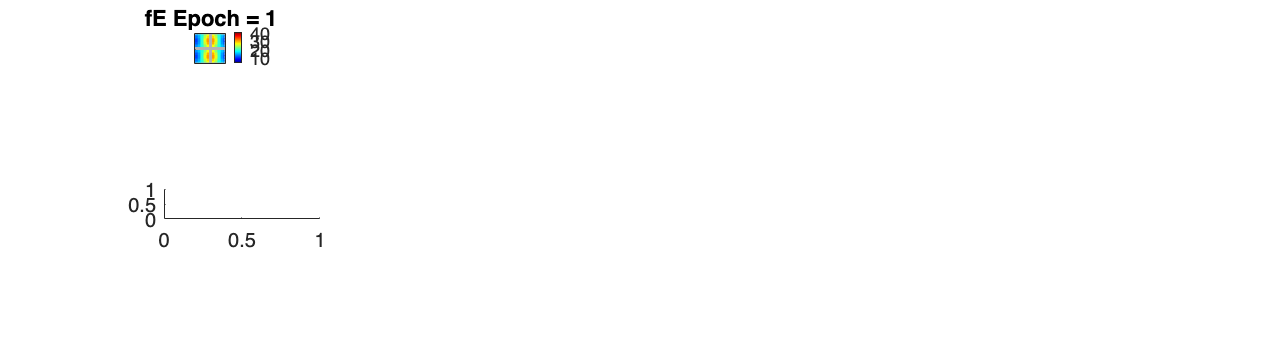

Fig3 = figure("Name",sprintf('RealL6'),...
    'units','normalized','outerposition',[0,0,1,1]);
TestId = 1;
PlotId = 1;
for Epoch =  [1,2,3,4,5,6,7,8, 51, 301] %[1 50:50:300]%
    subplot(4,5,PlotId)
   fEMap = LDEOutAll{TestId}{Epoch}.S*(1-CplxR)+LDEOutAll{TestId}{Epoch}.C*CplxR;
    ShowField_Rec(...
        fEMap,...
        ...%LDEOutAll{TestId}{end}.I,...
        1:PixNumOut,N_HCOutX*NPixX,N_HCOutY*NPixY)
    title(sprintf('fE Epoch = %d',...
        Epoch),...
        'Interpreter','tex')
    axis([0.5 20.5 10.5 30.5])
    axis square
    caxis([3 40]);

    subplot(4,5,PlotId + 10)
    FieldRow = N_HCOutY * NPixY;
    FieldCol = floor(length(fEMap)/FieldRow);
    L4Efield = reshape(fEMap,FieldRow,FieldCol); 
    L4Efield_padded = padarray(L4Efield, [1, 1], 'circular'); % Pad B for periodic boundary conditions    
    C = conv2(L4Efield_padded, L6Kernel, 'same'); % Perform convolution with periodic boundary conditions  
    %% The slope of L6 is adjustable
    L6EUse = L6Convert(C(2:end-1, 2:end-1),L6pars);

    ShowField_Rec(...
        L6EUse(:),...
        ...%LDEOutAll{TestId}{end}.I,...
        1:PixNumOut,N_HCOutX*NPixX,N_HCOutY*NPixY)
    title(sprintf('fL6 Epoch = %d',...
        Epoch),...
        'Interpreter','tex')
    axis([0.5 20.5 10.5 30.5])
    axis square
    caxis([3 99]);

    PlotId = PlotId+1;
end

Save and Print Figs

FigName1 = sprintf('RealL6NewTest_L6par%.1f-%d-%d-%d_%.1fdeg',L6pars{1},L6pars{3},L6pars{4},L6pars{5},AngleInpt);
savefig(Fig3,[FigurePaperPath FigName1 '.fig']);

Fig3.PaperUnits = 'centimeters';
Fig3.PaperSize = [36,28];
Fig3.PaperOrientation = "landscape";
exportgraphics(Fig3,[FigurePaperPath FigName1 '.pdf'],'Resolution',150)
close all

Two other figs

Fig4 = figure("Name",'L6-properties');
subplot 121
xx = 0:50;
plot(xx,L6Convert(xx,L6pars),'--r');
xlabel('convoluted L4')
ylabel('fL6')
ylim([0 99])
grid on
hold on
plot(xx, L6pars{1}*(xx-L6pars{2}),'b')

subplot 122
plot(L2DiffNormNeib{TestId})
title('2-norm diff from the end')
set(gca,'YScale','log')


FigName2 = sprintf('RealL6NewTest_L6par%.1f-%d-%d-%d_%.1fdeg_info',L6pars{1},L6pars{3},L6pars{4},L6pars{5},AngleInpt);
savefig(Fig4,[FigurePaperPath FigName2 '.fig']);

Fig4.PaperUnits = 'centimeters';
Fig4.PaperSize = [36,28];
Fig4.PaperOrientation = "landscape";
exportgraphics(Fig4,[FigurePaperPath FigName2 '.pdf'],'Resolution',150)
close all